clc; clearvars; close all;
cd(fileparts(matlab.desktop.editor.getActiveFilename));

filePath1 = '../../stiletto_imuData//IMU1//datalog00002.TXT';
filePath2 = '../../stiletto_imuData//IMU2Or3//datalog00024.TXT';
filePath3 = '../../stiletto_imuData//IMU3Or2//datalog00013.TXT';
%filePath4 = 'stiletto_imuData//IMU4//datalog00004.TXT';

IMU1_S = readtable(strcat(filePath1));

IMU2_S = readtable(strcat(filePath2));

IMU3_S = readtable(strcat(filePath3));

%IMU4_S = readtable(strcat(filePath4));

## Format accelerometer data

% milli-g's  -->  g's
IMU1_S = formatUnits(IMU1_S);
IMU2_S = formatUnits(IMU2_S);
IMU3_S = formatUnits(IMU3_S);
%IMU4_S = formatUnits(IMU4_S);



## aX

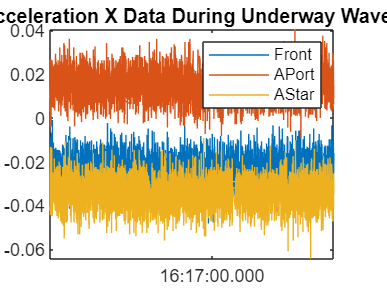


% Underway (10 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aX, IMU2_S.gps_Time,IMU2_S.aX,...
     IMU3_S.gps_Time,IMU3_S.aX)%, IMU4_S.gps_Time,IMU4_S.aX)
uw1 = "16:13:00.000";
uw2 = "16:20:00.000";
uw1 = duration(uw1);
uw2 = duration(uw2);
xlim([uw1,uw2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')
title('IMU Acceleration X Data During Underway Wave State')

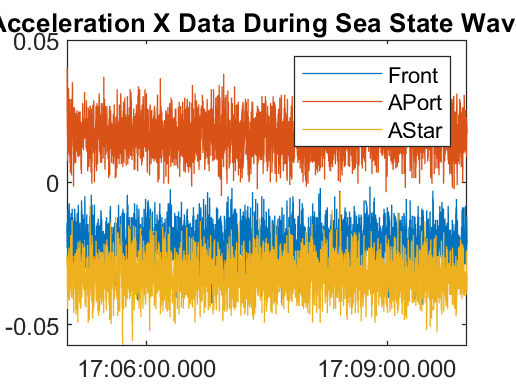


% Seastate (20 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aX, IMU2_S.gps_Time,IMU2_S.aX,...
     IMU3_S.gps_Time,IMU3_S.aX)%, IMU4_S.gps_Time,IMU4_S.aX)
ss1 = "17:05:00.000";
ss2 = "17:10:00.000";
ss1 = duration(ss1);
ss2 = duration(ss2);
xlim([ss1,ss2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')
title('IMU Acceleration X Data During Sea State Wave State')

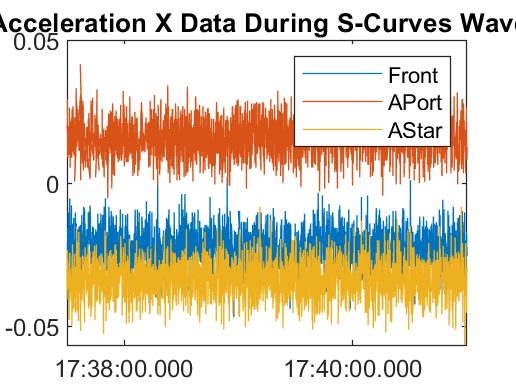


% S-Curves (20 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aX, IMU2_S.gps_Time,IMU2_S.aX,...
     IMU3_S.gps_Time,IMU3_S.aX)%, IMU4_S.gps_Time,IMU4_S.aX)
sc1 = "17:37:30.000";
sc2 = "17:41:00.000";
sc1 = duration(sc1);
sc2 = duration(sc2);
xlim([sc1,sc2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')
title('IMU Acceleration X Data During S-Curves Wave State')

## aY

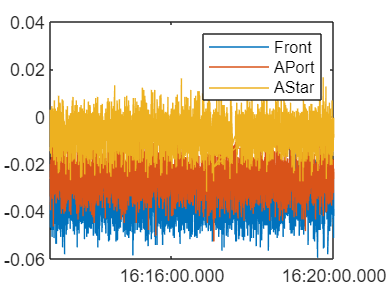

% Underway (10 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aY, IMU2_S.gps_Time,IMU2_S.aY,...
     IMU3_S.gps_Time,IMU3_S.aY)%, IMU4_S.gps_Time,IMU4_S.aY)
% uw1 = "16:13:00.000";
% uw2 = "16:20:00.000";
% uw1 = duration(uw1);
% uw2 = duration(uw2);
xlim([uw1,uw2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')

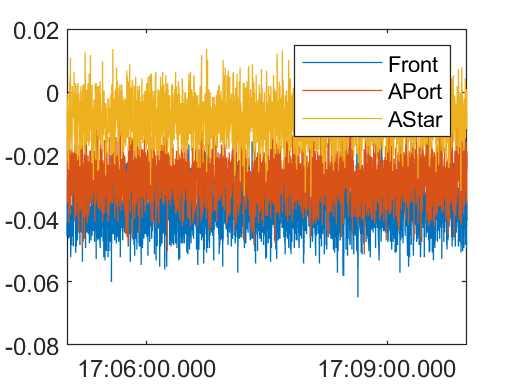


% Seastate (20 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aY, IMU2_S.gps_Time,IMU2_S.aY,...
     IMU3_S.gps_Time,IMU3_S.aY)%, IMU4_S.gps_Time,IMU4_S.aY)
% ss1 = "17:05:00.000";
% ss2 = "17:10:00.000";
% ss1 = duration(ss1);
% ss2 = duration(ss2);
xlim([ss1,ss2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')

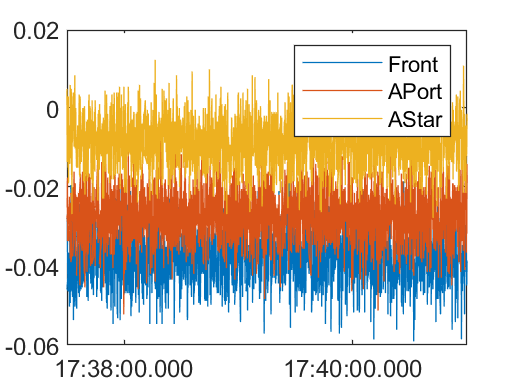


% S-Curves (20 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aY, IMU2_S.gps_Time,IMU2_S.aY,...
     IMU3_S.gps_Time,IMU3_S.aY)%, IMU4_S.gps_Time,IMU4_S.aY)
% sc1 = "17:37:30.000";
% sc2 = "17:41:00.000";
% sc1 = duration(sc1);
% sc2 = duration(sc2);
xlim([sc1,sc2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')

## aZ

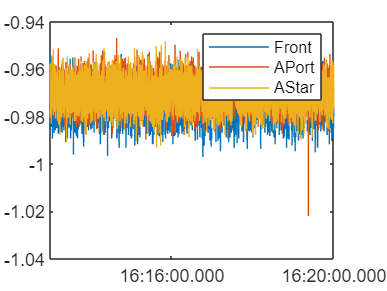

% Underway (10 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aZ, IMU2_S.gps_Time,IMU2_S.aZ,...
     IMU3_S.gps_Time,IMU3_S.aZ)%, IMU4_S.gps_Time,IMU4_S.aZ)
% uw1 = "16:13:00.000";
% uw2 = "16:20:00.000";
% uw1 = duration(uw1);
% uw2 = duration(uw2);
xlim([uw1,uw2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')

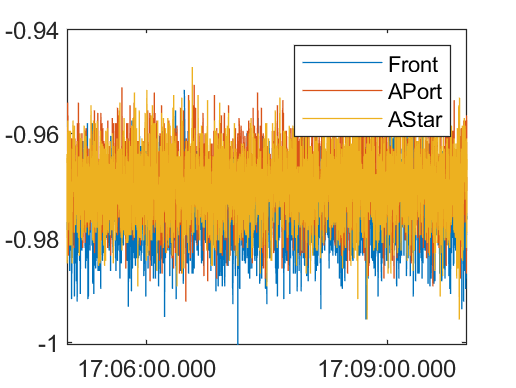


% Seastate (20 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aZ, IMU2_S.gps_Time,IMU2_S.aZ,...
     IMU3_S.gps_Time,IMU3_S.aZ)%, IMU4_S.gps_Time,IMU4_S.aZ)
% ss1 = "17:05:00.000";
% ss2 = "17:10:00.000";
% ss1 = duration(ss1);
% ss2 = duration(ss2);
xlim([ss1,ss2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')

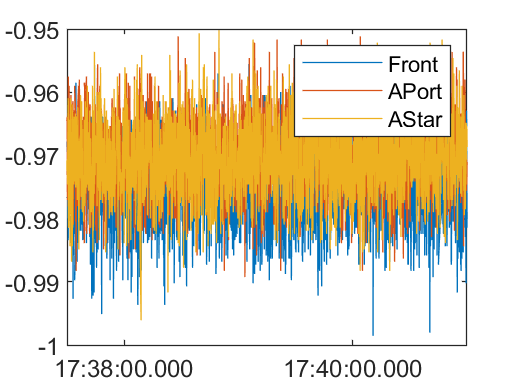


% S-Curves (20 kn)
figure
plot(IMU1_S.gps_Time,IMU1_S.aZ, IMU2_S.gps_Time,IMU2_S.aZ,...
     IMU3_S.gps_Time,IMU3_S.aZ)%, IMU4_S.gps_Time,IMU4_S.aZ)
% sc1 = "17:37:30.000";
% sc2 = "17:41:00.000";
sc1 = duration(sc1);
sc2 = duration(sc2);
xlim([sc1,sc2]);
%ylim([-160000,100000,])
legend('Front','APort','AStar')%,'Spot')

## Extract data

uw.i = uw1;     uw.f = uw2;
ss.i = ss1;     ss.f = ss2;
sc.i = sc1;     sc.f = sc2;

[IMU1] = get_aXYZ(IMU1_S, uw, ss, sc);
[IMU2] = get_aXYZ(IMU2_S, uw, ss, sc);
[IMU3] = get_aXYZ(IMU3_S, uw, ss, sc);
% [IMU4] = get_aXYZ(IMU4_S, uw, ss, sc);

IMU1.uw.title = 'Underway (10 kn)';
IMU2.uw.title = 'Underway (10 kn)';
IMU3.uw.title = 'Underway (10 kn)';

IMU1.ss.title = 'Sea State (20 kn)';
IMU2.ss.title = 'Sea State (20 kn)';
IMU3.ss.title = 'Sea State (20 kn)';

IMU1.sc.title = 'S-Curves (20 kn)';
IMU2.sc.title = 'S-Curves (20 kn)';
IMU3.sc.title = 'S-Curves (20 kn)';

## FFT Accel


IMU1.uw = imuFFT(IMU1.uw);
IMU2.uw = imuFFT(IMU2.uw);
IMU3.uw = imuFFT(IMU3.uw);

IMU1.ss = imuFFT(IMU1.ss);
IMU2.ss = imuFFT(IMU2.ss);
IMU3.ss = imuFFT(IMU3.ss);

IMU1.sc = imuFFT(IMU1.sc);
IMU2.sc = imuFFT(IMU2.sc);
IMU3.sc = imuFFT(IMU3.sc);


## Init IMU Accel


IMU1.uw = initAccel(IMU1.uw);
IMU2.uw = initAccel(IMU2.uw);
IMU3.uw = initAccel(IMU3.uw);

IMU1.ss = initAccel(IMU1.ss);
IMU2.ss = initAccel(IMU2.ss);
IMU3.ss = initAccel(IMU3.ss);

IMU1.sc = initAccel(IMU1.sc);
IMU2.sc = initAccel(IMU2.sc);
IMU3.sc = initAccel(IMU3.sc);

## Accel -> Disp

IMU1.uw = accel2disp(IMU1.uw);
IMU1.ss = accel2disp(IMU1.ss);
IMU1.sc = accel2disp(IMU1.sc);

IMU2.uw = accel2disp(IMU2.uw);
IMU2.ss = accel2disp(IMU2.ss);
IMU2.sc = accel2disp(IMU2.sc);

IMU3.uw = accel2disp(IMU3.uw);
IMU3.ss = accel2disp(IMU3.ss);
IMU3.sc = accel2disp(IMU3.sc);

## Plot Disp

% plotDisp(IMU1.uw, IMU2.uw, IMU3.uw)
% plotDisp(IMU1.ss, IMU2.ss, IMU3.ss)
% plotDisp(IMU1.sc, IMU2.sc, IMU3.sc)

## FFT Vel


IMU1.uw = imuV_FFT(IMU1.uw);
IMU2.uw = imuV_FFT(IMU2.uw);
IMU3.uw = imuV_FFT(IMU3.uw);

IMU1.ss = imuV_FFT(IMU1.ss);
IMU2.ss = imuV_FFT(IMU2.ss);
IMU3.ss = imuV_FFT(IMU3.ss);

IMU1.sc = imuV_FFT(IMU1.sc);
IMU2.sc = imuV_FFT(IMU2.sc);
IMU3.sc = imuV_FFT(IMU3.sc);

## Remove signals from FFT & Plot sinwave

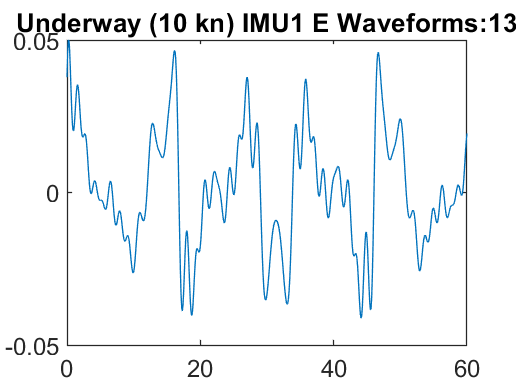

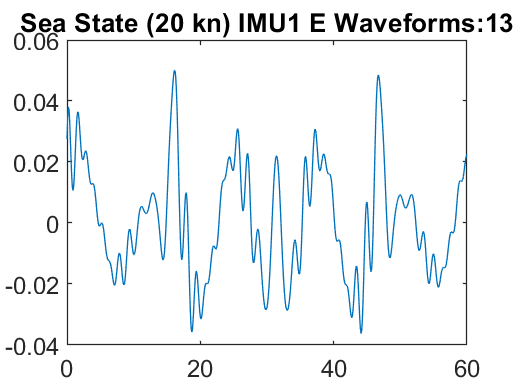

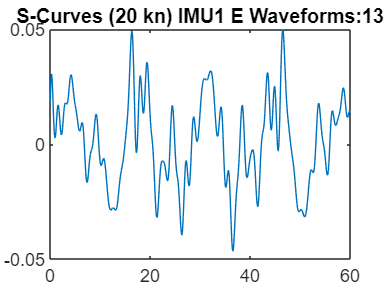

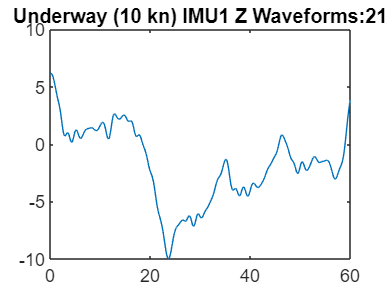

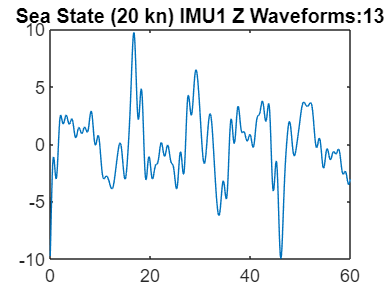

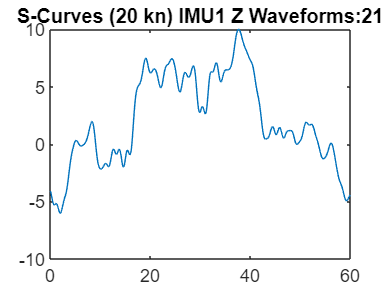

IMU1 = cyclFiltr(IMU1, 'IMU1');

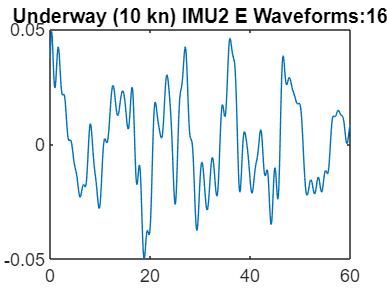

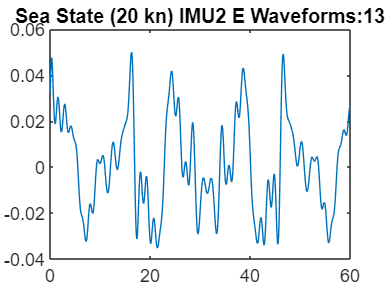

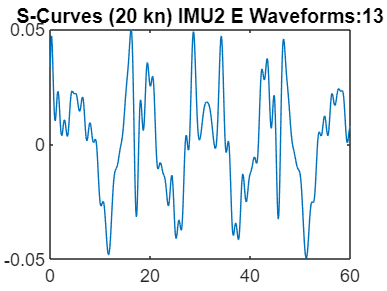

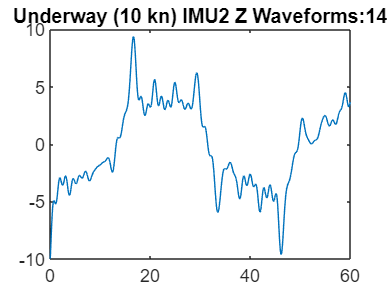

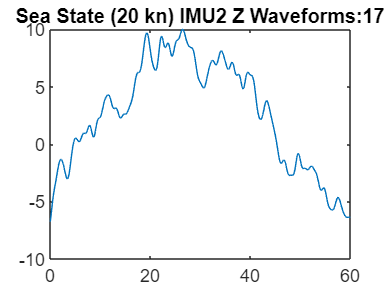

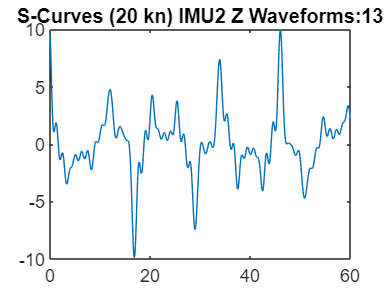

IMU2 = cyclFiltr(IMU2, 'IMU2');

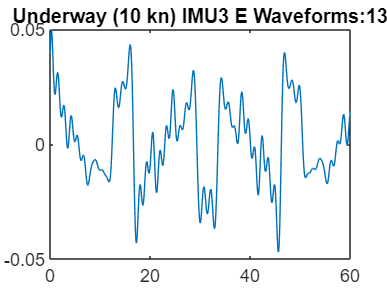

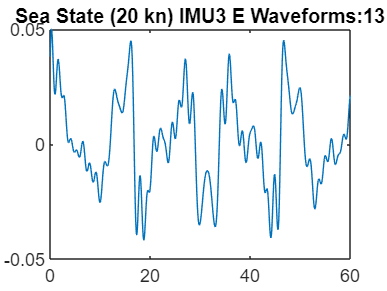

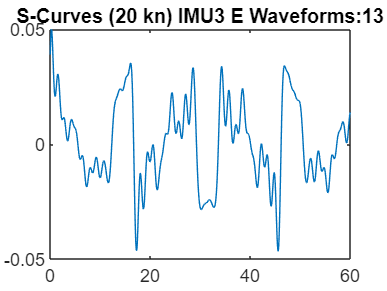

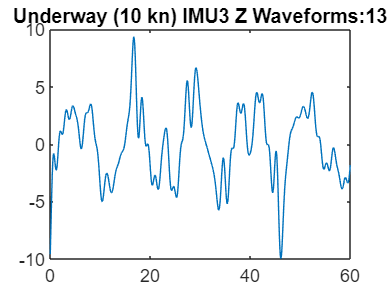

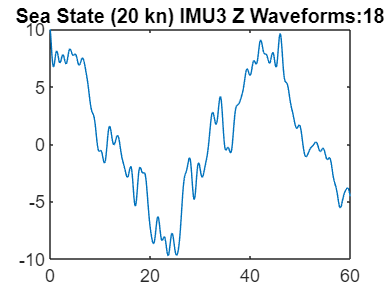

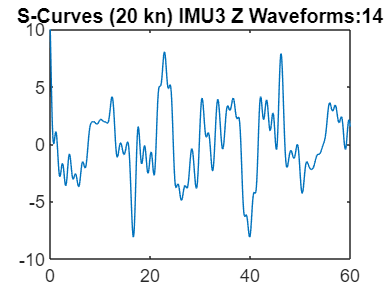

IMU3 = cyclFiltr(IMU3, 'IMU3');

## Create Equation text file

equFile = fopen('allEquations.txt', 'wt');
writeEqu2File(IMU1, 'IMU1', equFile);
writeEqu2File(IMU2, 'IMU2', equFile);
writeEqu2File(IMU3, 'IMU3', equFile);
fclose(equFile);

## Functions

function imu = formatUnits(imu)
    imu.aX = imu.aX / 1000;
    imu.aY = imu.aY / 1000;
    imu.aZ = imu.aZ / 1000;
 
end


function IMU = get_aXYZ(IMU_S, uw, ss, sc)
    [IMU_S, uw, ss, sc] = getTimestampIndex(IMU_S, uw, ss, sc);
    
    IMU.uw = extract(IMU_S, uw.i_ind, uw.f_ind);
    IMU.ss = extract(IMU_S, ss.i_ind, ss.f_ind);
    IMU.sc = extract(IMU_S, sc.i_ind, sc.f_ind);
end


function IMU = extract(IMU_S, i1, i2)
    index = (i2 - i1 + 1);
    IMU.aY = zeros(index,1);
    IMU.aZ = zeros(index,1);
    IMU.aTime = zeros(index,1);
    
    for i = 1:index
        IMU.aX(i)   = IMU_S.aX((i1-1)+i);
        IMU.aY(i)   = IMU_S.aY((i1-1)+i);
        IMU.aZ(i)   = IMU_S.aZ((i1-1)+i);
    end

    if size(IMU.aX, 1) < size(IMU.aX, 2)
        IMU.aX = IMU.aX';
    end
  
    for i = 2:index
        IMU.aTime(i) = IMU.aTime(i-1) + 0.1;
    end
end


function IMU_ts = initAccel(IMU_ts)
    
    ave_aX = mean(IMU_ts.aX);
    ave_aY = mean(IMU_ts.aY);
    ave_aZ = mean(IMU_ts.aZ);

    IMU_ts.aX = IMU_ts.aX - ave_aX;
    IMU_ts.aY = IMU_ts.aY - ave_aY;
    IMU_ts.aZ = IMU_ts.aZ - ave_aZ;
end
  

function [IMU_S, uw, ss, sc] = getTimestampIndex(IMU_S, uw, ss, sc)
    uw1_imu_i = 0;     uw2_imu_i = 0;
    ss1_imu_i = 0;     ss2_imu_i = 0;
    sc1_imu_i = 0;     sc2_imu_i = 0;
    
    for i = 1:size(IMU_S.gps_Time)
        % Underway
        if uw1_imu_i == 0
            if IMU_S.gps_Time(i) >= uw.i
                uw1_imu_i = i;
            end
        end
        if uw2_imu_i == 0
            if IMU_S.gps_Time(i) >= uw.f
                uw2_imu_i = i;
            end
        end
    
        % Sea State
        if ss1_imu_i == 0
            if IMU_S.gps_Time(i) >= ss.i
                ss1_imu_i = i;
            end
        end
        if ss2_imu_i == 0
            if IMU_S.gps_Time(i) >= ss.f
                ss2_imu_i = i;
            end
        end
    
        % S-Curves
        if sc1_imu_i == 0
            if IMU_S.gps_Time(i) >= sc.i
                sc1_imu_i = i;
            end
        end
        if sc2_imu_i == 0
            if IMU_S.gps_Time(i) >= sc.f
                sc2_imu_i = i;
            end
        end
    end
    
    uw.i_ind = uw1_imu_i;
    ss.i_ind = ss1_imu_i;
    sc.i_ind = sc1_imu_i;
    uw.f_ind = uw2_imu_i;
    ss.f_ind = ss2_imu_i;
    sc.f_ind = sc2_imu_i;

end


function [imuTimestamp] = accel2disp(imuTimestamp)

    ts = imuTimestamp;
%{
    % Accel -> Veloc
    % da * dt = v  (dt = Fs = 10hz = 0.1s)
    for i = 1:size(ts.aX,1)-1
        ts.vX(i) = (ts.aX(i+1) - ts.aX(i)) * 0.1;
        ts.vY(i) = (ts.aY(i+1) - ts.aY(i)) * 0.1;
        ts.vZ(i) = (ts.aZ(i+1) - ts.aZ(i)) * 0.1;

        ts.vTime(i) = ts.aTime(i);
    end

    % Veloc -> Disp
    % dv * dt = d  (dt = Fs = 10hz = 0.1s)
    for i = 1:size(ts.vX,2)-1
        ts.dX(i) = (ts.vX(i+1) - ts.vX(i)) * 0.1;
        ts.dY(i) = (ts.vY(i+1) - ts.vY(i)) * 0.1;
        ts.dZ(i) = (ts.vZ(i+1) - ts.vZ(i)) * 0.1;

        ts.dTime(i) = ts.vTime(i);
    end
%}

    ts.vX = cumtrapz(ts.aX);
    ts.vY = cumtrapz(ts.aY);
    ts.vZ = cumtrapz(ts.aZ);
    ts.vTime = ts.aTime;

    ts.dX = cumtrapz(ts.vX);
    ts.dY = cumtrapz(ts.vY);
    ts.dZ = cumtrapz(ts.vZ);
    ts.dTime = ts.vTime;

    imuTimestamp = ts;
end


function IMU_ts = imuFFT(IMU_ts)

    [IMU_ts.ampaX,IMU_ts.fftaX,IMU_ts.fRangeaX] = plotFFT(IMU_ts.aX, 10, IMU_ts.title);
    [IMU_ts.ampaY,IMU_ts.fftaY,IMU_ts.fRangeaY] = plotFFT(IMU_ts.aY, 10, IMU_ts.title);
    [IMU_ts.ampaZ,IMU_ts.fftaZ,IMU_ts.fRangeaZ] = plotFFT(IMU_ts.aZ, 10, IMU_ts.title);
end
%
function IMU_ts = imuV_FFT(IMU_ts)
    IMU_ts.vE = euclidean(IMU_ts.vX, IMU_ts.vY);

    [IMU_ts.ampvX,IMU_ts.fftvX,IMU_ts.fRangevX] = plotFFT(IMU_ts.vX(1000:1100), 10, IMU_ts.title);
    [IMU_ts.ampvY,IMU_ts.fftvY,IMU_ts.fRangevY] = plotFFT(IMU_ts.vY(1000:1100), 10, IMU_ts.title);
    [IMU_ts.ampvZ,IMU_ts.fftvZ,IMU_ts.fRangevZ] = plotFFT(IMU_ts.vZ(1000:1100), 10, IMU_ts.title);
    [IMU_ts.ampvE,IMU_ts.fftvE,IMU_ts.fRangevE] = plotFFT(IMU_ts.vE(1000:1100), 10, IMU_ts.title);
end


function vE = euclidean(vX, vY)
    vE = zeros(size(vX,1),1);
    
    for i = 1:size(vE, 1)
        vE(i) = sqrt(vX(i)^2 + vY(i)^2);
    end
end


function [P1,Y,f] = plotFFT(X, Fs, dtitle)
    L = size(X,1);
n = 2^nextpow2(L);
%    Y = fft(X);
Y = fft(X,n);
    
    P2 = abs(Y/L);
%    P1 = P2(1:L/2+1);
P1 = P2(1:n/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    ave = mean(P1);
%    RMS = rms(P1);

%    f = Fs*(0:(L/2))/L;
f = Fs*(0:(n/2))/n;

%     figure
%     plot(f,P1, f,P1, '.')
%     yline(ave)
%     title(dtitle)
%     xlabel("f (Hz)")
%     ylabel("|P1(f)|")
end


function plotDisp(imu1_ts, imu2_ts, imu3_ts)
    figure
    plot(imu1_ts.dTime, imu1_ts.vX, imu2_ts.dTime, imu2_ts.vX,...
         imu3_ts.dTime, imu3_ts.vX)
    title(strcat('Vel X: ', imu1_ts.title))
    legend('Front', 'APort', 'AStar')
    xlabel('Time [s]')
    ylabel('Displacement [m]')

    figure
    plot(imu1_ts.dTime, imu1_ts.vY, imu2_ts.dTime, imu2_ts.vY,...
         imu3_ts.dTime, imu3_ts.vY)
    title(strcat('Vel Y: ', imu1_ts.title))
    legend('Front', 'APort', 'AStar')
    xlabel('Time [s]')
    ylabel('Displacement [m]')

    figure
    plot(imu1_ts.dTime, imu1_ts.vZ, imu2_ts.dTime, imu2_ts.vZ,...
         imu3_ts.dTime, imu3_ts.vZ)
    title(strcat('Vel Z: ', imu1_ts.title))
    legend('Front', 'APort', 'AStar')
    xlabel('Time [s]')
    ylabel('Displacement [m]')
end


function IMU = cyclFiltr(IMU, imuNum)
    % Euclidean Displacement
    IMU.uw.waveDataE = filterPeaks(IMU.uw.fftvE,    IMU.uw.ampvE,...
                                   IMU.uw.fRangevE, IMU.uw.title, ...
                                   imuNum, 'E');
    IMU.ss.waveDataE = filterPeaks(IMU.ss.fftvE,    IMU.ss.ampvE,...
                                   IMU.ss.fRangevE, IMU.ss.title, ...
                                   imuNum, 'E');
    IMU.sc.waveDataE = filterPeaks(IMU.sc.fftvE,    IMU.sc.ampvE,...
                                   IMU.sc.fRangevE, IMU.sc.title, ...
                                   imuNum, 'E');

    IMU.uw.waveDataZ = filterPeaks(IMU.uw.fftvZ,    IMU.uw.ampvZ,...
                                   IMU.uw.fRangevZ, IMU.uw.title, ...
                                   imuNum, 'Z');
    IMU.ss.waveDataZ = filterPeaks(IMU.ss.fftvZ,    IMU.ss.ampvZ,...
                                   IMU.ss.fRangevZ, IMU.ss.title, ...
                                   imuNum, 'Z');
    IMU.sc.waveDataZ = filterPeaks(IMU.sc.fftvZ,    IMU.sc.ampvZ,...
                                   IMU.sc.fRangevZ, IMU.sc.title, ...
                                   imuNum, 'Z');
end


function d = filter(uFFT, uAmp, f, limit)
    amp = zeros(size(uAmp,1),1);
    phase = zeros(size(uAmp,1),1);
    hz = f';
    w = 0;

    for i = 1:size(uAmp, 1)
        if uAmp(i) > limit
            amp(i) = uAmp(i);
            phase(i) = angle(uFFT(i));

            w = w + 1;
            d.amp(w) = amp(i);
            d.hz(w) = hz(i);
            d.phase(w) = phase(i);
        else
            hz(i) = 0;
        end
    end

end


function d = filterPeaks(uFFT, uAmp, f, ts, imuNum, dir)
    amp = zeros(size(uAmp,1),1);
    phase = zeros(size(uAmp,1),1);
    hz = f';
    w = 0;
    prevAmp = uAmp(1);

    for i = 1:size(uAmp, 1)-1
        if uAmp(i) > prevAmp        % if sorted amp > prior amp
            if uAmp(i) > uAmp(i+1)  %    and if > next amp
                amp(i) = uAmp(i);
                phase(i) = angle(uFFT(i));
    
                w = w + 1;
                d.amp(w) = amp(i);      % Sets filtered amp to peak
                d.hz(w) = hz(i);        % Sets filtered hz  to peak
                d.phase(w) = phase(i);  % Sets filtered phase to peak
            end
        end
        prevAmp = uAmp(i);
    end
    d = plotWave(d, ts, imuNum, dir);
end


function d = plotWave(d, ts, imuNum, dir)
    time = 1*60;
    d.time = 0:0.1:time;
    d.angle = zeros(size(d.time,2),1);
    d.equation = '';

    for i = 1:size(d.amp, 2)
        if dir == 'Z'
            for t = 1:size(d.time, 2)
                d.angle(t) = d.angle(t) + (d.amp(i)*sin(d.hz(i) * d.time(t) + d.phase(i)));
            end
    
            amp  = compose("%.5f", d.amp(i));    
            freq = compose("%.3f", d.hz(i));    
            phaz = compose("%.3f", d.phase(i));
            d.equation = strcat(d.equation,'+',amp,'*SIN(',phaz,'+',freq,'*TIME)');

        elseif dir == 'E'       % xy data needs to be integrated (make -cos)
            for t = 1:size(d.time, 2)
                d.angle(t) = d.angle(t) + (d.amp(i)*-cos(d.hz(i) * d.time(t) + d.phase(i)));
            end
    
            amp  = compose("%.5f", d.amp(i));    
            freq = compose("%.3f", d.hz(i));    
            phaz = compose("%.3f", d.phase(i));
            d.equation = strcat(d.equation,'+',amp,'*COS(',phaz,'+',freq,'*TIME)');
        end
    end
    
    d.equation = eraseBetween(d.equation, 1,1);
    
    maxA = max(d.angle);
    minB = min(d.angle);
    maxMag = max(abs(maxA), abs(minB));
    mag = string(maxMag);

    if dir == 'Z'
%         d.angle = d.angle*20/(maxA-minB) - (maxMag*20/(maxA-minB) - 10);
        d.angle = d.angle * 10/maxMag;
        d.equation = strcat('(10/',mag,')*(',d.equation,')');
    elseif dir == 'E'
%         d.angle = d.angle*0.1/(maxA-minB) - (maxMag*0.1/(maxA-minB) - 0.05);
        d.angle = d.angle * -0.05/maxMag;
        d.equation = strcat('(-0.05/',mag,')*(',d.equation,')');
    end
    
    figure
    plot(d.time, d.angle)
    titleName = strcat(ts, {' '}, imuNum, {' '}, dir,' Waveforms: ', num2str(i));
    title(titleName)
end


function writeEqu2File(imu, imunum, equFile)
    fprintf(equFile, '---------------------\n');
    sortEqu2File(imu.uw, imunum, 'uw', equFile);
    fprintf(equFile, '-\n');
    sortEqu2File(imu.ss, imunum, 'ss', equFile);
    fprintf(equFile, '-\n');
    sortEqu2File(imu.sc, imunum, 'sc', equFile);
    fprintf(equFile, '-\n');
end


function sortEqu2File(imutf, imunum, nametf, equFile)
    fprintf(equFile, '%s_%s_Pitch: %s\n', imunum, nametf, imutf.waveDataZ.equation);
    fprintf(equFile, '%s_%s__Sway: %s\n', imunum, nametf, imutf.waveDataE.equation);
end




